## **01USHLO - Driver Assistance System Design **

### **Project 4 - Anti-lock Braking System design**

set(0,'defaultAxesFontName', 'Times New Roman',...
'defaultTextFontName', 'Times New Roman',...
'defaultAxesFontSize', 12,...
'defaultTextFontSize', 12,...
'defaultLineLineWidth',2,...
'DefaultAxesXGrid','on',...
'DefaultAxesYGrid','on',...
'DefaultTextInterpreter','Tex')

#### Exercise 1: Driveline Model – Braking

clc
close all
clear
VehicleParameters;
load('LUT_values.mat');
Ts = 1e-3;
n_vec = n_compact;
T_vec = T_compact;
sigma_vec = sigma;
mu_vec = mu_dry;
V0 = 80/3.6;
omega0 = V0/Re;
Jdf = Jwf+Jt/tau_f^2;
Jdr = Jwr;
hc = 1; 

## braking maneuver - Speed and slip trends

Task - Run a braking maneuver from 80 kmph and analyze speed and slip trends.

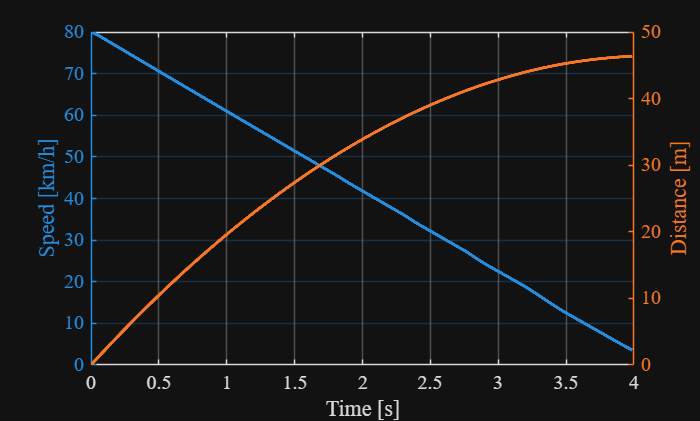

Traction = 2;
ha = 0;
t_pedalAct = 0.2;
t_shifting = 0.6;
n_shiftup = 450;
n_shiftdown = 140;
startingGear = 5;
gear_vec = i_g;
Kb = 2.33;
TbTot   = 3000; % total brake force
Tbf_max = TbTot/(1 + 1/Kb); 
Tbr_max = Tbf_max/Kb; 

% braking command:
hb = 0.25;

% simulation:
out = sim("Exercise1.slx");

figure
yyaxis left
plot(out.Speed.time, out.Speed.signals.values*3.6)
xlabel('Time [s]')
ylabel('Speed [km/h]')
yyaxis right
plot(out.Distance.time, out.Distance.signals.values)
ylabel('Distance [m]')

% return
figure
hold;

Current plot held


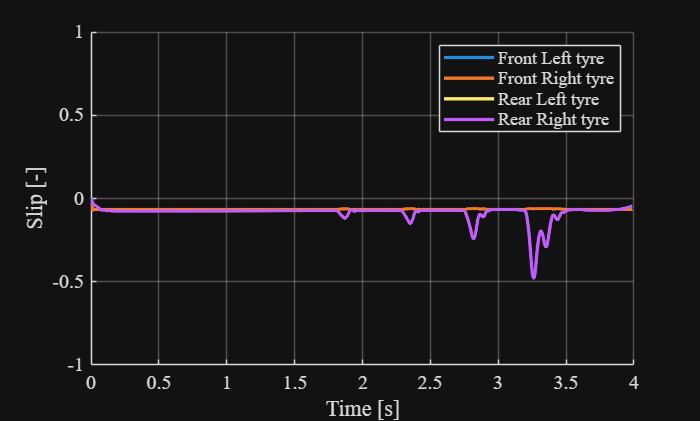

plot(out.slip.time, out.slip.signals(1).values)
plot(out.slip.time, out.slip.signals(2).values)
plot(out.slip.time, out.slip.signals(3).values)
plot(out.slip.time, out.slip.signals(4).values)
legend('Front Left tyre', 'Front Right tyre', 'Rear Left tyre', 'Rear Right tyre')
xlabel('Time [s]')
ylabel('Slip [-]')
ylim([-1 1])

% return

1) Analyze the effect of $h_{b\;}$and $K_{b\;}$on stopping distance.

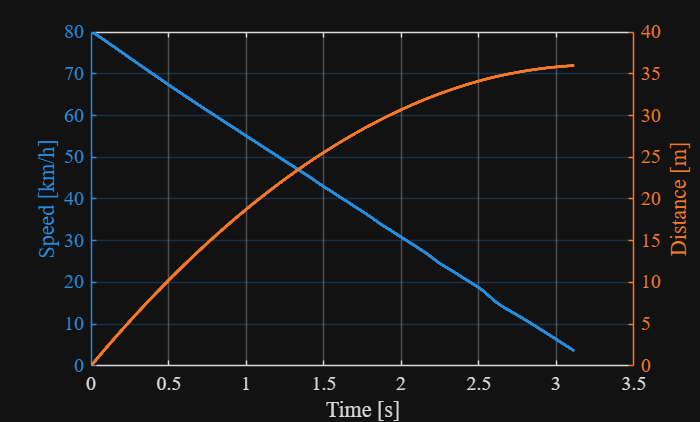

Traction = 1;
hb = 0.35; % brake command
Kb = 2.3;  % Kb: front/rear brake ratio 
TbTot   = 3000;                  % total brake force
Tbf_max = TbTot/(1 + 1/Kb); 
Tbr_max = Tbf_max/Kb; 

out = sim("Exercise1.slx");

figure
yyaxis left
plot(out.Speed.time, out.Speed.signals.values*3.6)
xlabel('Time [s]')
ylabel('Speed [km/h]')
yyaxis right
plot(out.Distance.time, out.Distance.signals.values)
ylabel('Distance [m]')

figure
hold;

Current plot held


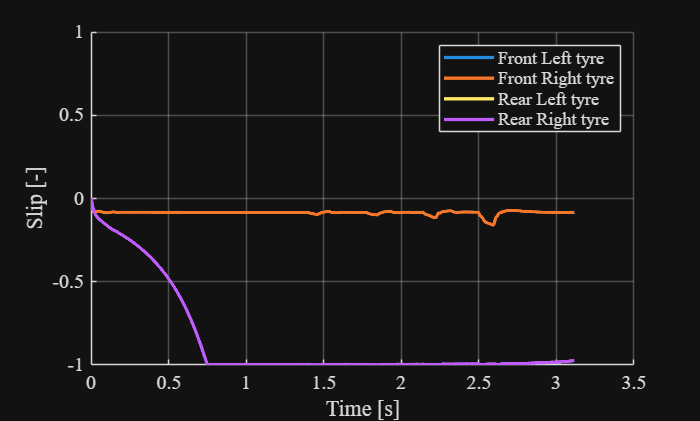

plot(out.slip.time, out.slip.signals(1).values)
plot(out.slip.time, out.slip.signals(2).values)
plot(out.slip.time, out.slip.signals(3).values)
plot(out.slip.time, out.slip.signals(4).values)
legend('Front Left tyre', 'Front Right tyre', 'Rear Left tyre', 'Rear Right tyre')
xlabel('Time [s]')
ylabel('Slip [-]')
ylim([-1 1])

2) Analyze stopping distance sensitivity to vehicle mass and drag coefficient in a ±15% range.

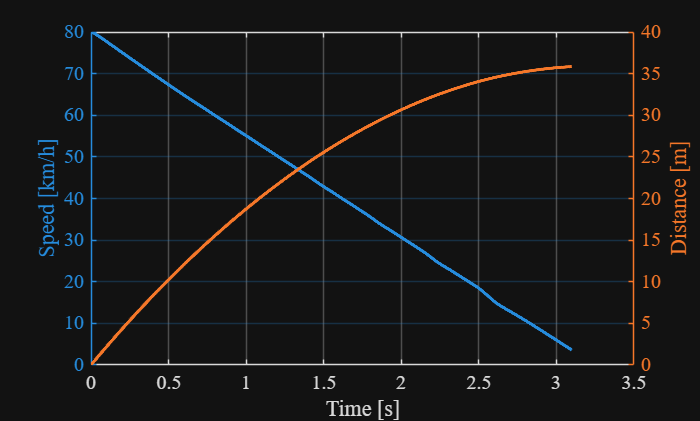

mass_coeff = 0.99;
m = m*mass_coeff;
Cx_coeff = 0.97;
Cx = Cx*Cx_coeff;

% braking condition:
hb = 0.35;
Kb = 2.3; % Kb: brake distribution factor. Usually from 50/50 to 70/30
TbTot   = 3000; % total brake force
Tbf_max = TbTot/(1 + 1/Kb); 
Tbr_max = Tbf_max/Kb; 

out = sim("Exercise1.slx");

figure
yyaxis left
plot(out.Speed.time, out.Speed.signals.values*3.6)
xlabel('Time [s]')
ylabel('Speed [km/h]')
yyaxis right
plot(out.Distance.time, out.Distance.signals.values)
ylabel('Distance [m]')


figure
hold;

Current plot held


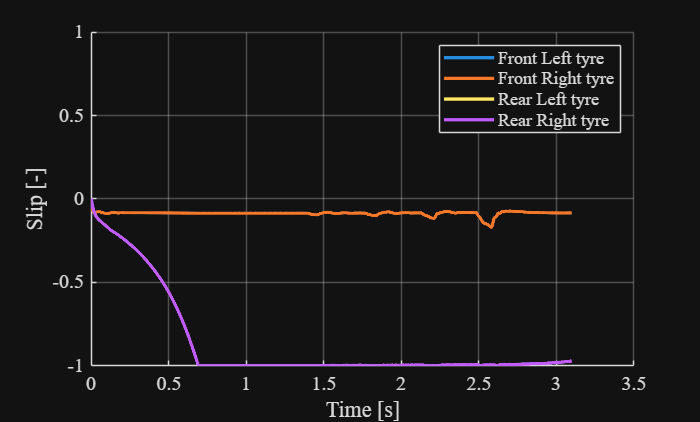

plot(out.slip.time, out.slip.signals(1).values)
plot(out.slip.time, out.slip.signals(2).values)
plot(out.slip.time, out.slip.signals(3).values)
plot(out.slip.time, out.slip.signals(4).values)
legend('Front Left tyre', 'Front Right tyre', 'Rear Left tyre', 'Rear Right tyre')
xlabel('Time [s]')
ylabel('Slip [-]')
ylim([-1 1])

3) Compare the results obtained in the previous points to the stopping distance obtained with Neutral gear ($h_{c\;}$= 0).


Traction = 1;
ha = 0;
hc = 0; % Neutral! See hc and switch inside "engine + clutch" block
t_pedalAct   = 0.2;
t_shifting   = 0.6;
n_shiftup    = 450;
n_shiftdown  = 140;
startingGear = 5;
gear_vec     = i_g;
% Kb = 2.33; % 70/30 
% hb = 100;
Kb = 2.3;
Tbr_max = Tbf_max/Kb;
hb = 0.35;



neutral = sim("Exercise1.slx");
hc = 1;
out = sim("Exercise1.slx");
figure
hold;

Current plot held


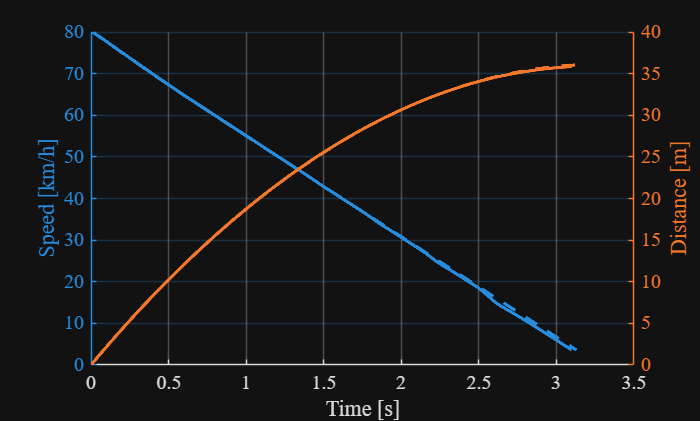

yyaxis left
plot(out.Speed.time, out.Speed.signals.values*3.6)
plot(neutral.Speed.time, neutral.Speed.signals.values*3.6)
xlabel('Time [s]')
ylabel('Speed [km/h]')
yyaxis right
plot(out.Distance.time, out.Distance.signals.values)
plot(neutral.Distance.time, neutral.Distance.signals.values)
ylabel('Distance [m]')


figure
hold;

Current plot held


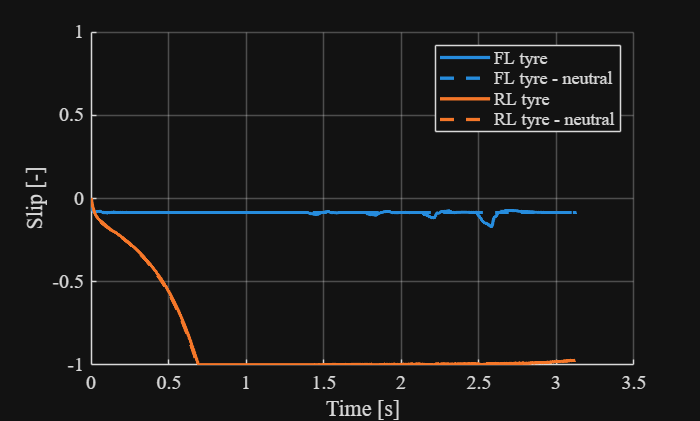

plot(out.slip.time, out.slip.signals(1).values, 'SeriesIndex',1, 'DisplayName', 'FL tyre')
plot(neutral.slip.time, neutral.slip.signals(1).values, '--', 'SeriesIndex',1, 'DisplayName', 'FL tyre - neutral')

% plot(out.slip.time, out.slip.signals(2).values, 'SeriesIndex',2, 'DisplayName', 'FR tyre')
% plot(neutral.slip.time, neutral.slip.signals(2).values, '--', 'SeriesIndex',2, 'DisplayName', 'FR tyre - neutral')

plot(out.slip.time, out.slip.signals(3).values, 'SeriesIndex',2, 'DisplayName', 'RL tyre')
plot(neutral.slip.time, neutral.slip.signals(3).values, '--', 'SeriesIndex',2,'DisplayName', 'RL tyre - neutral')

% plot(out.slip.time, out.slip.signals(4).values, 'SeriesIndex',4, 'DisplayName', 'RR tyre')
% plot(neutral.slip.time, neutral.slip.signals(4).values, '--', 'SeriesIndex',4, 'DisplayName', 'RR tyre - neutral')

xlabel('Time [s]')
ylabel('Slip [-]')
ylim([-1 1])
legend()

#### Exercise 2: ABS Controller for Wheel Slip Regulation

1) Complete the Simulink scheme of «Exercise1.slx» with the following controller on each wheel and run the simulation with $K_{\textrm{gain}}$ = -600.


$$\left\lbrace \begin{array}{ll}
\dot{u} =K_{\textrm{gain}} \textrm{sign}\left(\sigma_r -\sigma \;\right) & \\
T_{\textrm{brake}} =\textrm{sat}\left(u,0,T_{b\left(f,r\right)} \right) & 
\end{array}\right.$$


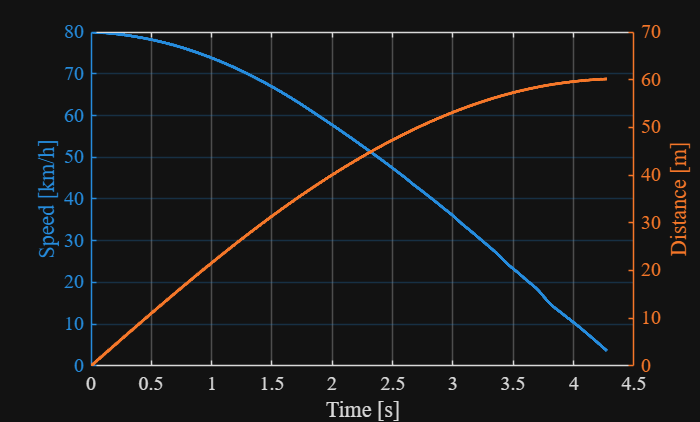

Kb = 2.3;
Tbr_max = Tbf_max/Kb;
hb = 0.35;

Traction = 1;


sigma_r = -0.2;
K_gain  = -600;
out = sim("Exercise2.slx");

figure
yyaxis left
plot(out.Speed.time, out.Speed.signals.values*3.6)
xlabel('Time [s]')
ylabel('Speed [km/h]')
yyaxis right
plot(out.Distance.time, out.Distance.signals.values)
ylabel('Distance [m]')


figure
hold;

Current plot held


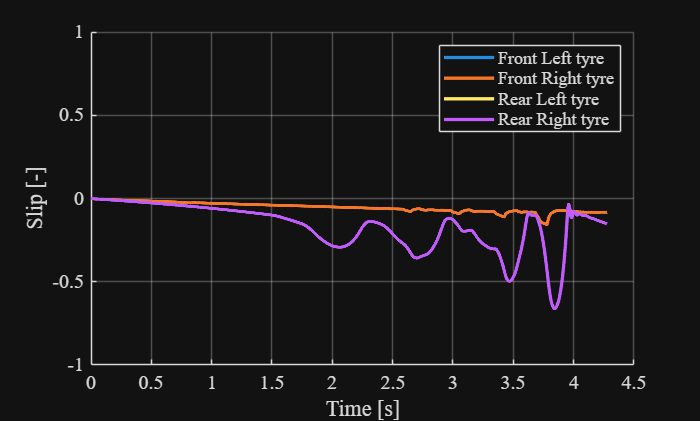

plot(out.slip.time, out.slip.signals(1).values)
plot(out.slip.time, out.slip.signals(2).values)
plot(out.slip.time, out.slip.signals(3).values)
plot(out.slip.time, out.slip.signals(4).values)
legend('Front Left tyre', 'Front Right tyre', 'Rear Left tyre', 'Rear Right tyre')
xlabel('Time [s]')
ylabel('Slip [-]')
ylim([-1 1])

%return

2) Explain why the value of $\sigma_r$ was selected as -0.2 and what would happen if it was set to -0.1 and -0.3 respectively. Compare the results of the simulations, especially the slip trend.

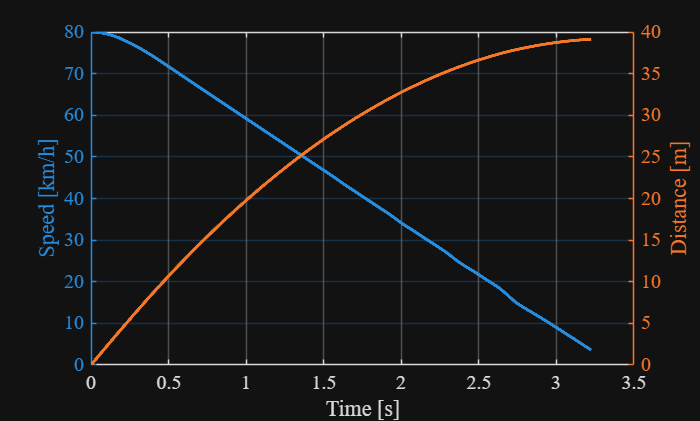


sigma_r = -0.1;
K_gain = -5000;
hc = 1;
out = sim("Exercise2.slx");
figure
yyaxis left
plot(out.Speed.time, out.Speed.signals.values*3.6)
xlabel('Time [s]')
ylabel('Speed [km/h]')
yyaxis right
plot(out.Distance.time, out.Distance.signals.values)
ylabel('Distance [m]')

figure
hold;

Current plot held


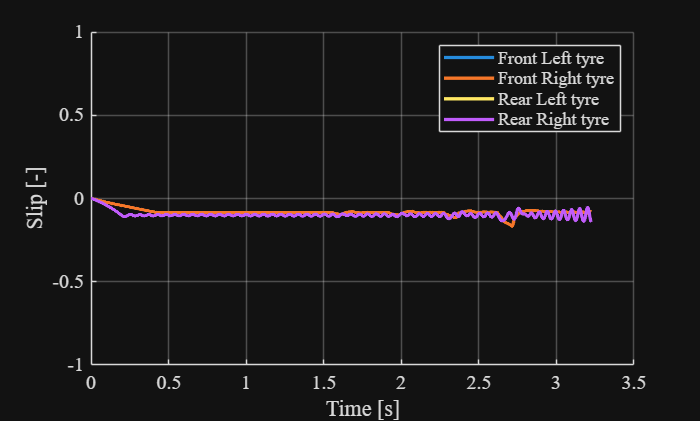

plot(out.slip.time, out.slip.signals(1).values)
plot(out.slip.time, out.slip.signals(2).values)
plot(out.slip.time, out.slip.signals(3).values)
plot(out.slip.time, out.slip.signals(4).values)
legend('Front Left tyre', 'Front Right tyre', 'Rear Left tyre', 'Rear Right tyre')
xlabel('Time [s]')
ylabel('Slip [-]')
ylim([-1 1])

3) Tune the value of $K$keeping the value of $\sigma_r$ at -0.2 to achieve minimum stopping distance

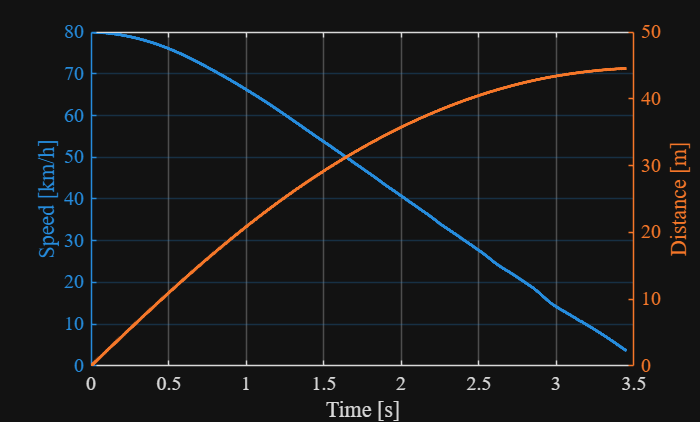

K_gain = -1650;
sigma_r = -0.2;
out = sim("Exercise2.slx");

figure
yyaxis left
plot(out.Speed.time, out.Speed.signals.values*3.6)
xlabel('Time [s]')
ylabel('Speed [km/h]')
yyaxis right
plot(out.Distance.time, out.Distance.signals.values)
ylabel('Distance [m]')


figure
hold;

Current plot held


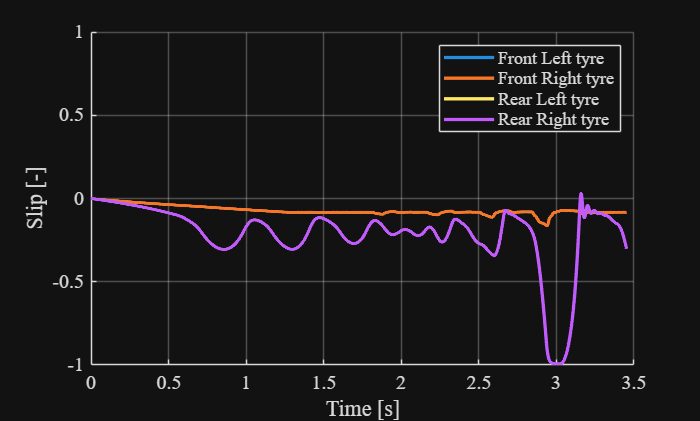

plot(out.slip.time, out.slip.signals(1).values)
plot(out.slip.time, out.slip.signals(2).values)
plot(out.slip.time, out.slip.signals(3).values)
plot(out.slip.time, out.slip.signals(4).values)
legend('Front Left tyre', 'Front Right tyre', 'Rear Left tyre', 'Rear Right tyre')
xlabel('Time [s]')
ylabel('Slip [-]')
ylim([-1 1])

4) Repeat point 3 assuming wet conditions (modify the $\mu -\sigma {\;}_r$ block accordingly) and discuss the different results.  

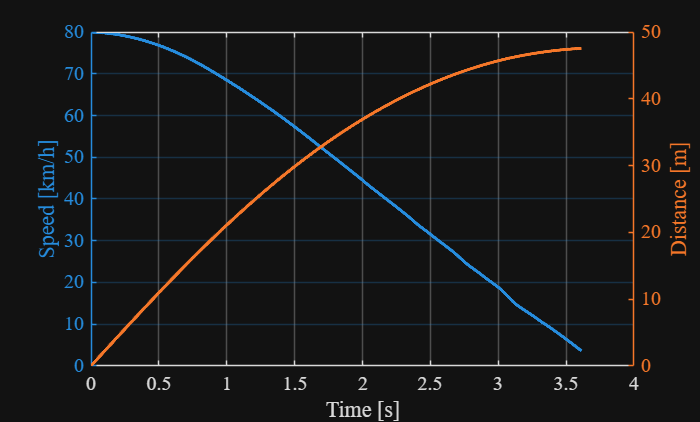


VehicleParameters;
roadcondition = 1;
switch roadcondition
    case 1
        mu_vec = mu_dry;
    case 2
        mu_vec = mu_wet;
end
K_gain = -1280;
sigma_r = -0.2;
out = sim("Exercise2.slx");

figure
yyaxis left
plot(out.Speed.time, out.Speed.signals.values*3.6)
xlabel('Time [s]')
ylabel('Speed [km/h]')
yyaxis right
plot(out.Distance.time, out.Distance.signals.values)
ylabel('Distance [m]')

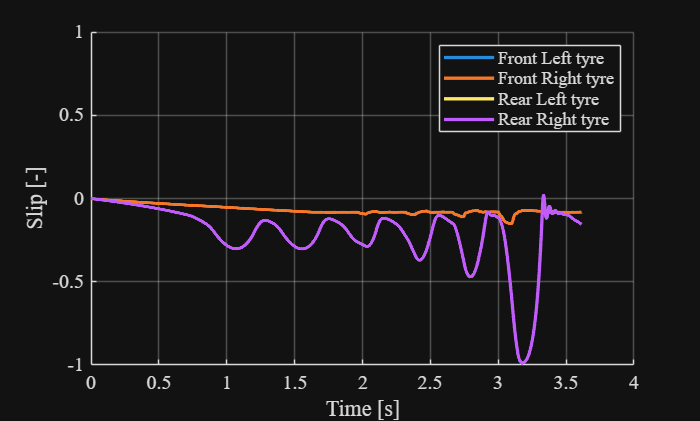


figure
hold on;
plot(out.slip.time, out.slip.signals(1).values)
plot(out.slip.time, out.slip.signals(2).values)
plot(out.slip.time, out.slip.signals(3).values)
plot(out.slip.time, out.slip.signals(4).values)
legend('Front Left tyre', 'Front Right tyre', 'Rear Left tyre', 'Rear Right tyre')
xlabel('Time [s]')
ylabel('Slip [-]')
ylim([-1 1])

5) Discuss whether or not the control presented in this exercise can be installed on a vehicle or not and its practical relevance.

## Exercise 3. ABS - Conjugate Boundary Method

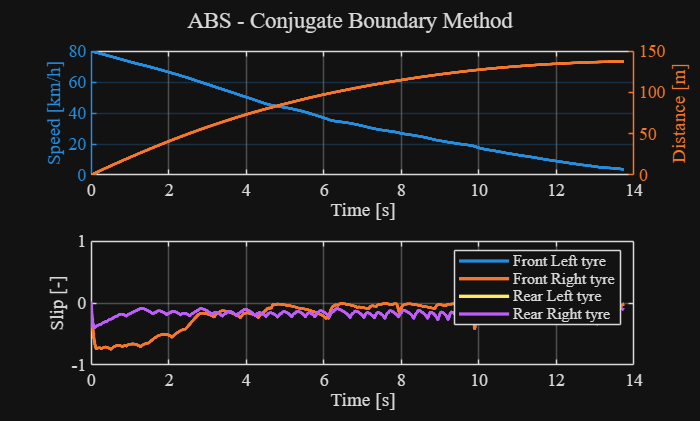

VehicleParameters;
load('LUT_values.mat');
mu_vec = mu_snow;       % wet conditions
Kb = 1.8;            % brake balance front/rear brake ratio
TbTot   = 3000;     % Max brake force
Tbf_max = TbTot / (1 + 1/Kb);  % max front braking torque
Tbr_max = Tbf_max / Kb;        % max rear braking torque
hb      = 0.5;      % brake command
hc      = 1;
Traction = 1;
V0 = 80/3.6;       % initial speed
K1 = 40;      % m/s^2
K3 = 35;       % m/s^2
K2 = 60e-3;     % sec
K_release = 5500; % Nm/s
K_reapply = 200;  % Nm/s

out = sim("Exercise3.slx");
figure
subplot(2,1,1)
sgtitle('ABS - Conjugate Boundary Method')
yyaxis left
plot(out.Speed.time, out.Speed.signals.values*3.6); hold on;
xlabel('Time [s]')
ylabel('Speed [km/h]')
yyaxis right
plot(out.Distance.time, out.Distance.signals.values)
ylabel('Distance [m]')
subplot(2,1,2)
plot(out.slip.time, out.slip.signals(1).values); hold on;
plot(out.slip.time, out.slip.signals(2).values)
plot(out.slip.time, out.slip.signals(3).values)
plot(out.slip.time, out.slip.signals(4).values)
legend('Front Left tyre', 'Front Right tyre', 'Rear Left tyre', 'Rear Right tyre')
xlabel('Time [s]')
ylabel('Slip [-]')
ylim([-1 1])